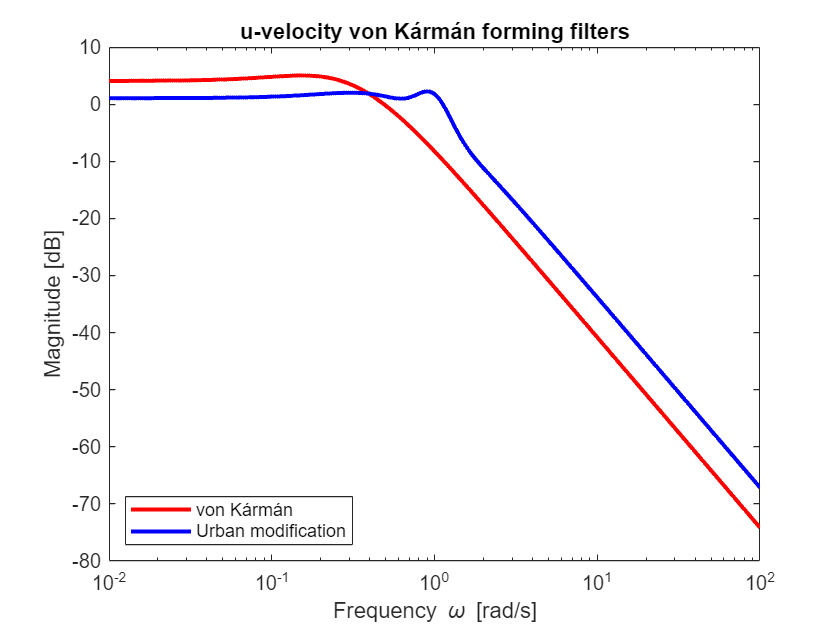

% Urban-modified longitudinal Bode (example)
omega = logspace(-2, 2, 1000);
L = 20; U = 10; omega_peak = U / L;
gain = 30;  % in dB

L = 200;    % Turbulence scale [m]
U = 50;     % Mean wind speed [m/s]
sigma_u = 1; % Not used for Bode shape

Omega = omega * L / U;
% Transfer function magnitude |H(omega% Frequency vector
omega = logspace(-2, 2, 1000);  % rad/s
log_omega = log10(omega);

% ==== Von Kármán Longitudinal Filter ====
L = 200;    % Turbulence scale [m]
U = 50;     % Mean wind speed [m/s]

Omega = omega * L / U;
Hvk = sqrt(2 * L / (pi * U)) .* (1 + 8/3 * Omega.^2) ./ (1 + Omega.^2).^(11/6);
Hvk_dB = 20 * log10(Hvk);

% ==== Urban Modified Filter ====
L_urban = 20;
U_urban = 10;
Omega_urban = omega * L_urban / U_urban;

Hurb = sqrt(2 * L_urban / (pi * U_urban)) .* (1 + 8/3 * Omega_urban.^2) ./ ...
       (1 + Omega_urban.^2).^(11/6);

% Add resonance bump around 1 rad/s
resonance_bump = 10.^(5 * exp(-((log_omega - log10(1)).^2) / (2 * 0.1^2)) / 20);
Hurb = Hurb .* resonance_bump;

Hurb_dB = 20 * log10(Hurb);

% ==== Plot ====
figure;
semilogx(omega, Hvk_dB, 'r', 'LineWidth', 2.0); hold on;
semilogx(omega, Hurb_dB, 'b', 'LineWidth', 2.0);

xlabel('Frequency \omega [rad/s]')
ylabel('Magnitude [dB]')
title("u-velocity von Kármán forming filters")
legend("von Kármán", "Urban modification", 'Location', 'SouthWest')